## Updated plots by filtering the sessions

After filtering the sessions with:

Number of neurons > 200

Number of trials > 30 per direction

These are all the plots that are updated by this change.

### Figure 2

#### g - Effect on $I_0$

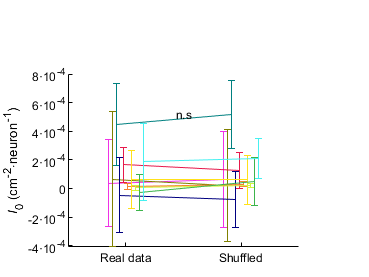

figure;
org.bns('I0', 'I0_s', true, false, true);
Utils.fix_exponent(gca,'y',0);
ylabel '{\itI}_0 (cm^{-2}\cdotneuron^{-1})'
figure_format([4 3]/2.5);
savefig('updated_figs/2g_effect_on_I0.fig');

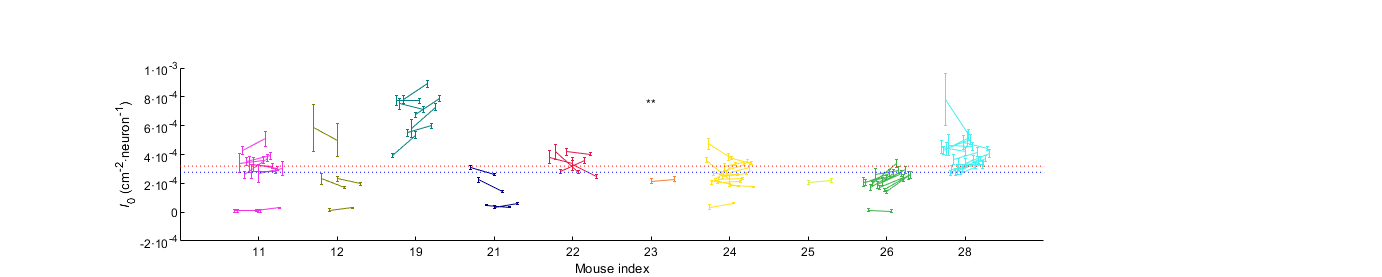

figure;
org.bns('I0', 'I0_s', false, false, true);
Utils.fix_exponent(gca,'y',0);
ylabel '{\itI}_0 (cm^{-2}\cdotneuron^{-1})'
xlabel 'Mouse index'
Utils.specific_format('MBNS');
savefig('updated_figs/2g_effect_on_I0_allsess.fig');

#### h - Effect on $I_0 N$

figure;
org.bns('I0N', 'I0N_s', true, true, true);

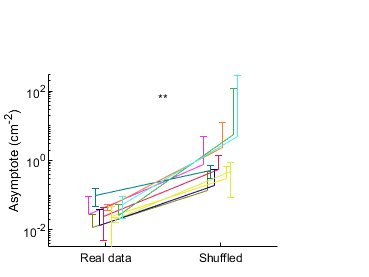

ylabel 'Asymptote (cm^{-2})'
ylim(10.^[-2.5 2.5]);
figure_format([4 3]/2.5);
savefig('updated_figs/2h_effect_on_I0N.fig');

figure;
org.bns('I0N', 'I0N_s', false, true, true);

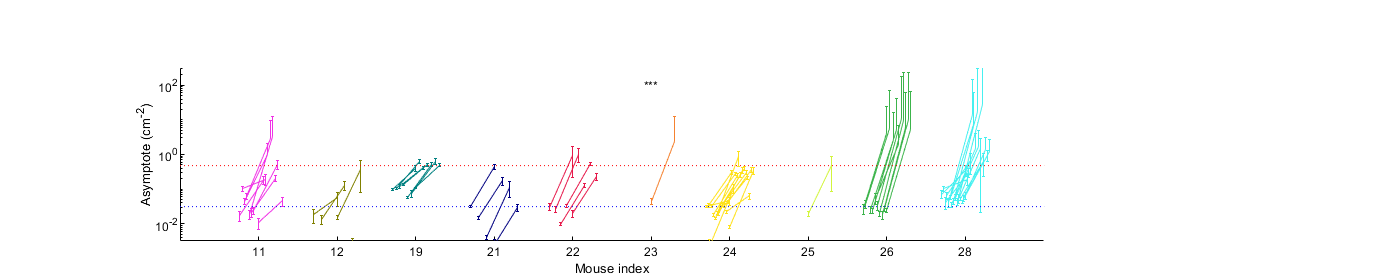

ylabel 'Asymptote (cm^{-2})'
ylim(10.^[-2.5 2.5]);
xlabel 'Mouse index'
Utils.specific_format('MBNS');
savefig('updated_figs/2h_effect_on_I0N_allsess.fig');

#### Effect on $N$

figure;
org.bns('N50', 'N50_s', true, true, true);

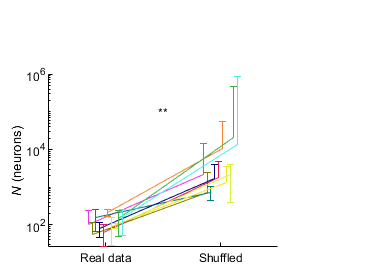

ylabel '{\itN} (neurons)'
%ylim(10.^[-2.5 2.5]);
figure_format([4 3]/2.5);
savefig('updated_figs/2_effect_on_N.fig');

figure;
org.bns('N50', 'N50_s', false, true, true);

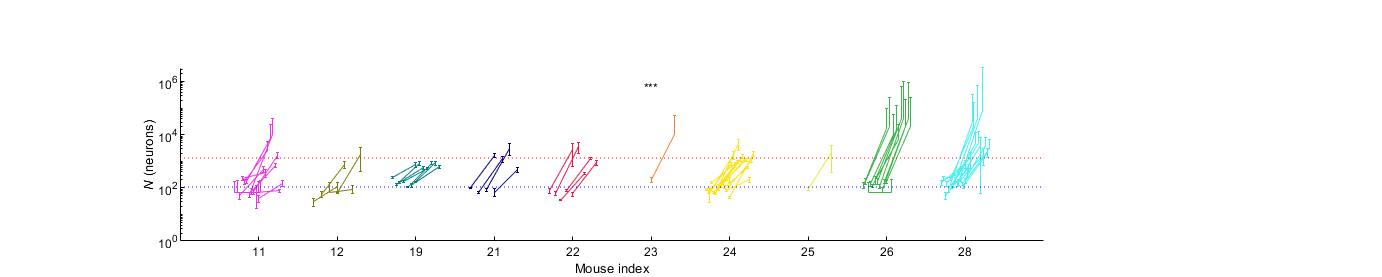

ylabel '{\itN} (neurons)'
%ylim(10.^[-2.5 2.5]);
xlabel 'Mouse index'
Utils.specific_format('MBNS');
savefig('updated_figs/2_effect_on_N_allsess.fig');

### Figure 3

#### f - Effect on asymptotic SNR

figure;
org.boxplot('asymp_snr', 'asymp_snr_shuf', true, true);

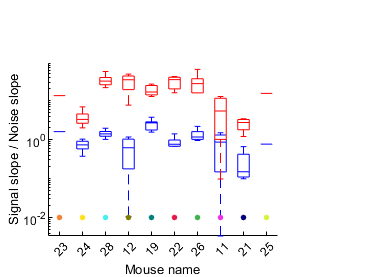

xlabel 'Mouse name'
ylabel 'Signal slope / Noise slope'
figure_format([4 3]/2.5);


figure;
org.bns('asymp_snr', 'asymp_snr_shuf', true, true, true);

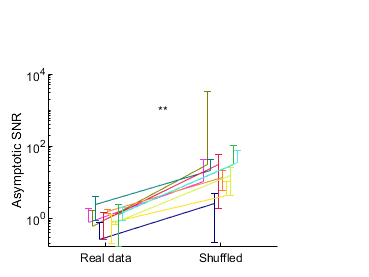

ylabel 'Asymptotic SNR'
figure_format([4 3]/2.5);
savefig('updated_figs/3f_effect_on_asymp_snr.fig');

figure;
org.bns('asymp_snr', 'asymp_snr_shuf', false, true, true);

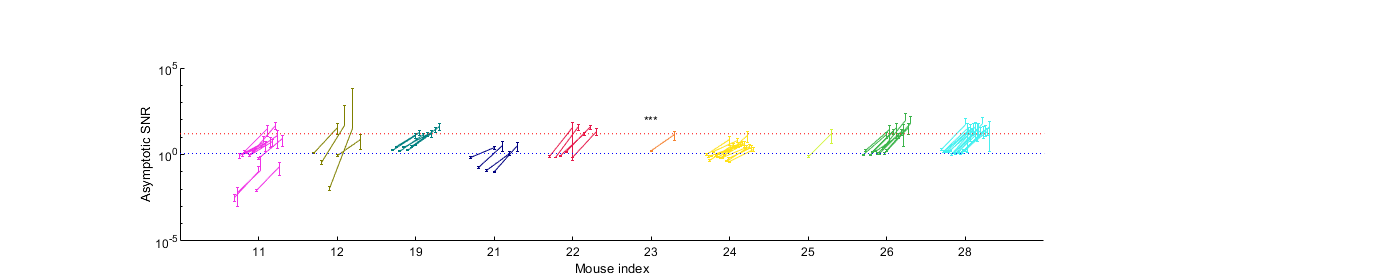

ylabel 'Asymptotic SNR'
xlabel 'Mouse index'
Utils.specific_format('MBNS');
savefig('updated_figs/3f_effect_on_asymp_snr_allsess.fig');

#### g - $I_0$ correspondence

figure;
org.correlogram('single_dp2', 'I0', true, true);

Using only 73 out of 110 sessions
Mouse-aggregated correlations single_dp2 vs. I0: adj. R^2 = 0.558
Pearson: 0.779, p = 7.901763e-03, **
Spearman: 0.333, p = 3.488462e-01, n.s
Kendall: 0.244, p = 3.807198e-01, n.s


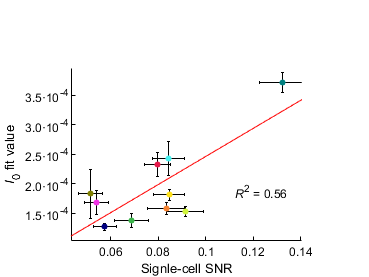

xlabel 'Single-cell SNR'
ylabel '{\itI}_0 fit value'
Utils.fix_exponent(gca, 'y', 1);
figure_format([4 3]/2.5);
savefig('updated_figs/3g_I0_correspondence.fig');

figure;
org.correlogram('single_dp2', 'I0', false, true);

Using only 73 out of 110 sessions
Sessionwise correlations single_dp2 vs. I0: adj. R^2 = 0.628
Pearson: 0.796, p = 3.979159e-17, ***
Spearman: 0.664, p = 1.527953e-10, ***
Kendall: 0.493, p = 7.159012e-10, ***


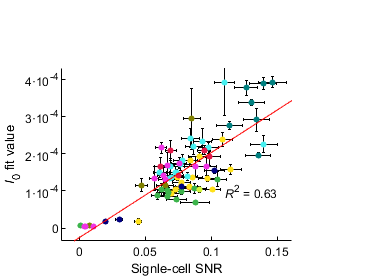

xlabel 'Signle-cell SNR'
ylabel '{\itI}_0 fit value'
Utils.fix_exponent(gca, 'y', 0);
figure_format([4 3]/2.5);
savefig('updated_figs/3g_I0_correspondence_allsess.fig');

#### h - Asymptotic correspondence

figure;
org.correlogram('asymp_snr', 'I0N', true, true);

Using only 73 out of 110 sessions
Mouse-aggregated correlations asymp_snr vs. I0N: adj. R^2 = 0.878
Pearson: 0.944, p = 3.972005e-05, ***
Spearman: 0.891, p = 1.380267e-03, **
Kendall: 0.733, p = 2.212853e-03, **


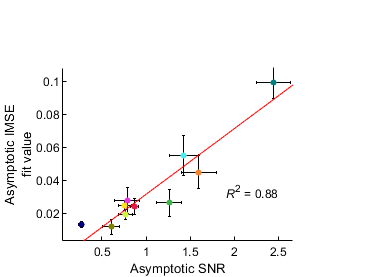

xlabel 'Asymptotic SNR'
ylabel(sprintf('Asymptotic IMSE\nfit value'));
figure_format([4 3]/2.5);
savefig('updated_figs/3h_I0N_correspondence.fig');

figure;
org.correlogram('asymp_snr', 'I0N', false, true);

Using only 73 out of 110 sessions
Sessionwise correlations asymp_snr vs. I0N: adj. R^2 = 0.551
Pearson: 0.747, p = 3.335100e-14, ***
Spearman: 0.750, p = 2.232519e-14, ***
Kendall: 0.572, p = 8.483301e-13, ***


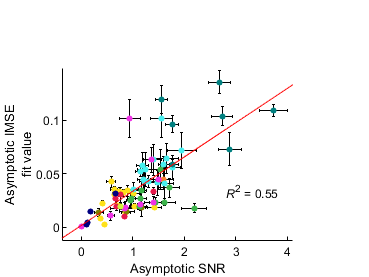

xlabel 'Asymptotic SNR'
ylabel(sprintf('Asymptotic IMSE\nfit value'));
figure_format([4 3]/2.5);
savefig('updated_figs/3h_I0N_correspondence_allsess.fig');

#### k (proposed) - Area between curves effect on $N_{50}$ (real - shuffled, up to PC10)

figure;
org.correlogram('delta_cos2_area_10', 'invN50', true, true);

Using only 73 out of 110 sessions
Mouse-aggregated correlations delta_cos2_area_10 vs. invN50: adj. R^2 = 0.499
Pearson: 0.745, p = 1.349775e-02, *
Spearman: 0.661, p = 4.402655e-02, *
Kendall: 0.511, p = 4.662257e-02, *


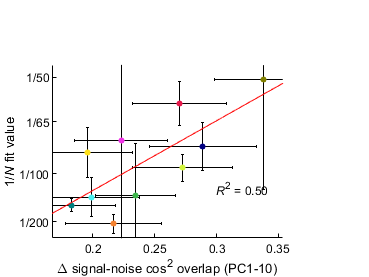

xlabel '\Delta signal-noise cos^2 overlap (PC1-10)'
ylabel '1/{\itN} fit value'
Nvals = [200 100 65 50];
Nlabels = arrayfun(@(x)['1/' num2str(x)],Nvals,'UniformOutput',false);
set(gca, 'YTick', 1./Nvals);
set(gca, 'YTickLabels', Nlabels);
figure_format([4 3]/2.5);
savefig('updated_figs/3k_N_correspondence.fig');

figure;
org.correlogram('delta_cos2_area_10', 'invN50', false, true);

Using only 73 out of 110 sessions
Sessionwise correlations delta_cos2_area_10 vs. invN50: adj. R^2 = 0.103
Pearson: 0.340, p = 3.292248e-03, **
Spearman: 0.416, p = 2.509327e-04, ***
Kendall: 0.274, p = 6.059851e-04, ***


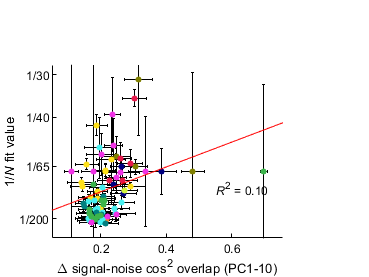

xlabel '\Delta signal-noise cos^2 overlap (PC1-10)'
ylabel '1/{\itN} fit value'
Nvals = [200 65 40 30];
Nlabels = arrayfun(@(x)['1/' num2str(x)],Nvals,'UniformOutput',false);
set(gca, 'YTick', 1./Nvals);
set(gca, 'YTickLabels', Nlabels);
figure_format([4 3]/2.5);
savefig('updated_figs/3k_N_correspondence_allsess.fig');

### Figure 4

#### h - Signal density and asymptotic ratio

figure;
org.correlogram('signal_density', 'asymp_ratio', true, true);

Special for asymp_ratio, removing outliers > 7
Using only 72 out of 110 sessions
Mouse-aggregated correlations signal_density vs. asymp_ratio: adj. R^2 = 0.851
Pearson: -0.931, p = 8.976670e-05, ***
Spearman: -0.903, p = 8.802250e-04, ***
Kendall: -0.778, p = 9.463183e-04, ***


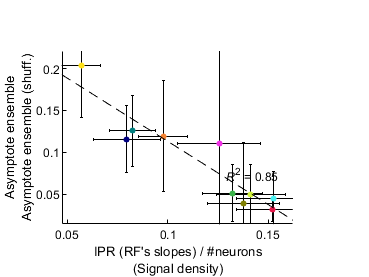

xlabel(sprintf('IPR (RF''s slopes) / #neurons\n(Signal density)'));
ylabel(sprintf('Asymptote ensemble\nAsymptote ensemble (shuff.)'));
figure_format([4 3]/2.5);
savefig('updated_figs/4h_signal_density.fig');
Utils.printto('updated_figs','4h_signal_density', true);

figure;
org.correlogram('signal_density', 'asymp_ratio', false, true);

Special for asymp_ratio, removing outliers > 7
Using only 72 out of 110 sessions
Sessionwise correlations signal_density vs. asymp_ratio: adj. R^2 = 0.542
Pearson: -0.740, p = 1.057594e-13, ***
Spearman: -0.802, p = 0.000000e+00, ***
Kendall: -0.601, p = 8.520965e-14, ***


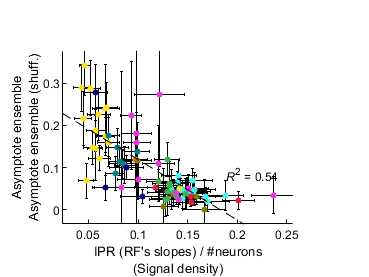

xlabel(sprintf('IPR (RF''s slopes) / #neurons\n(Signal density)'));
ylabel(sprintf('Asymptote ensemble\nAsymptote ensemble (shuff.)'));
figure_format([4 3]/2.5);
savefig('updated_figs/4h_signal_density_allsess.fig');